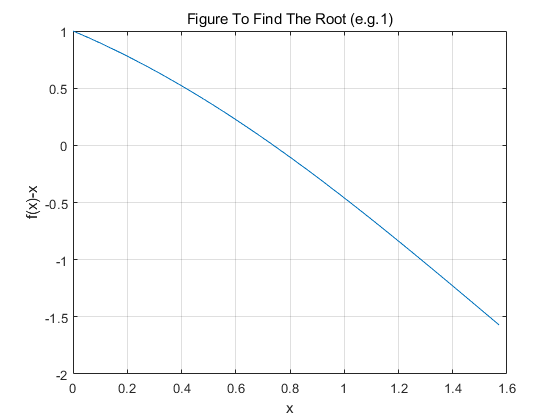

% Part1 Newton's Method
% Nonlinear root-finding problem
clc;clear;
format long ;

%% example 1 f(x) = cos(x)-x
% step 1 set up the function
syms t ;
f = @(t) cos(t) - t ;
df = diff( f , t ) ; % calculate derivative of function f

% step 2 draw the figure to find the general result
a  = 0 ; b = pi/2 ; % input the interval of the root-finding 
m = linspace( a , b , 100 ) ; 
n = f(m) ;
plot( m , n ) ; % draw the figure
grid on ;
title('Figure To Find The Root (e.g.1)') ;
xlabel('x') ; 
ylabel('f(x)-x') ;


% step 3 find and input the general root
k = 10 ; % number of overlaps
x = zeros( 1 , k ) ;
x(1) = pi/4; % input the general root
for i = 2 : k
    x(i) = x(i-1) - f( x(i-1) )/subs( df, t ,x(i-1) );
end
x'  % plot the roots

ans =    0.785398163397448
   0.739536133515238
   0.739085178106010
   0.739085133215161
   0.739085133215161
   0.739085133215161
   0.739085133215161
   0.739085133215161
   0.739085133215161
   0.739085133215161


laout(x',10,1)

0.785398163397448\\ \hline
0.739536133515238\\ \hline
0.739085178106010\\ \hline
0.739085133215161\\ \hline
0.739085133215161\\ \hline
0.739085133215161\\ \hline
0.739085133215161\\ \hline
0.739085133215161\\ \hline
0.739085133215161\\ \hline
0.739085133215161\\ \hline


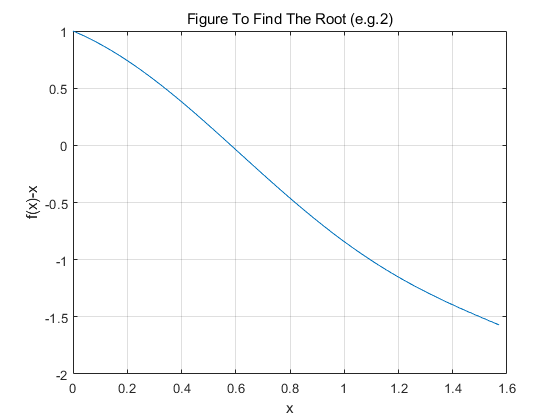



%% example 2 f(x) = cos^3(x)-x
clc;clear;
format long ;
% step 1 set up the function
syms t ;
f = @(t) cos(t).^3 - t ;
df = diff( f , t ) ; % calculate derivative of function f

% step 2 draw the figure to find the general result
a  = 0 ; b = pi/2 ; % input the interval of the root-finding 
m = linspace( a , b , 100 ) ; 
n = f(m) ;
plot( m , n ) ; % draw the figure
grid on ;
title('Figure To Find The Root (e.g.2)') ;
xlabel('x') ; 
ylabel('f(x)-x') ;


% step 3 find and input the general root
k = 10 ; % number of overlaps
x = zeros( 1 , k ) ;
x(1) = pi/5; % input the general root
for i = 2 : k
    x(i) = x(i-1) - f( x(i-1) )/subs( df, t ,x(i-1) );
end
x'  % plot the roots

ans =    0.628318530717959
   0.582448516983119
   0.582440071162041
   0.582440071158208
   0.582440071158208
   0.582440071158208
   0.582440071158208
   0.582440071158208
   0.582440071158208
   0.582440071158208


laout(x',10,1)

0.628318530717959\\ \hline
0.582448516983119\\ \hline
0.582440071162041\\ \hline
0.582440071158208\\ \hline
0.582440071158208\\ \hline
0.582440071158208\\ \hline
0.582440071158208\\ \hline
0.582440071158208\\ \hline
0.582440071158208\\ \hline
0.582440071158208\\ \hline
